# 活化分析计算靶核数

使用说明：提前创建单列能谱变量spec

注意 spec 是计数谱还是计数率谱，需要相应调整第2行

clearvars -except spec;close all;
sampleName = 'st740';
load(sampleName);
spec = s.spec{1,1}(:,2);
% thisdata = importdata('18.1mg.csv',',',42);
% spec = thisdata.data(:,2);
% spec = spec * 9*60*60; % cps or count?

注意 spec 是计数谱而非计数率谱

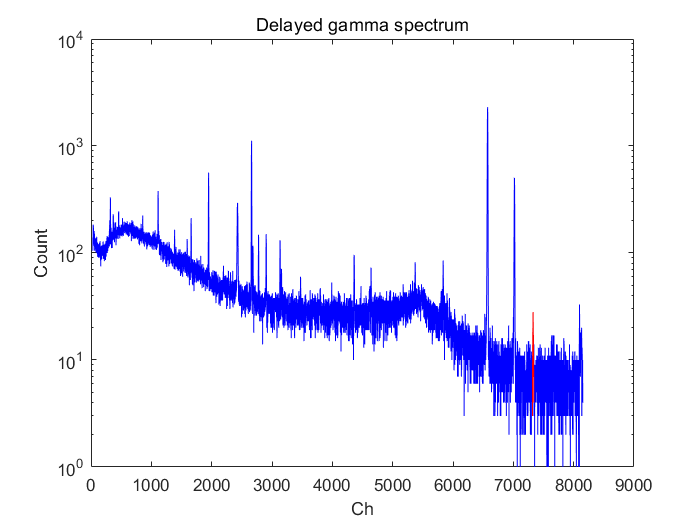

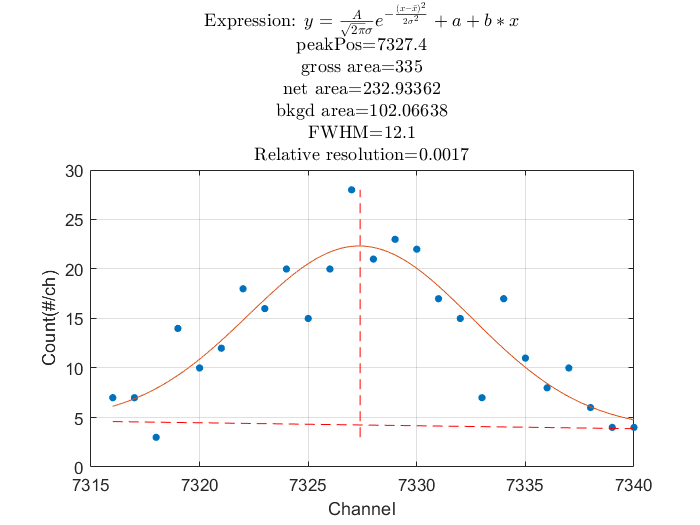

flux = 1e6; % nv
time_irr = 58*60; % s
load(['time_',sampleName,'.mat']);
% time_cool = 2682*60; %s
% time_det = 555*60; %s
eff_peak = 0.158; % 峰效率
roi = [7316:7340];


% xs = 98.65; % barn
% t_halflive = 2.69*24*60*60; %s
% m_a = 197; % 质量数
% e_charac = 0.411; % MeV
% eff_branch = 0.9562; % 释放该特征能量的分支比

load('ng_K41.mat');

for i = 1:length(spec)
if mod(spec(i),1)~=0
    error('Spectrum should be count spec, not count rate spec');
end
end
figure;
semilogy(spec,'b');hold on;
semilogy(roi,spec(roi),'r-');
xlabel('Ch');
ylabel('Count');
title('Delayed gamma spectrum');
figure;
[area,bkgd,~,~,~] = fitPeak(roi,spec(roi),1); % 净计数与本底计数

lambda = log(2)/t_halflive;% /s
factor_irr = 1-exp(-lambda*time_irr);
factor_cool = exp(-lambda*time_cool);
factor_det = 1-exp(-lambda*time_det);
% 计算核数量
n_atom = area/(flux*xs*1e-24*factor_irr*factor_cool*factor_det/lambda)/eff_peak/eff_branch;

% 计算注量率不确定度
err_area = sqrt(area+2*bkgd); 
err_n_atom = err_area/(flux*xs*1e-24*factor_irr*factor_cool*factor_det/lambda)/eff_peak/eff_branch;
disp(['Atoms:',num2str(n_atom/6.02e23,4),' ± ',num2str(err_n_atom/6.02e23,4),' mol']);

Atoms:0.0001353 ± 1.214e-05 mol


## 注量率最小探测限from Currie equation

nb = bkgd; % 本底计数
nd = 4.65*sqrt(nb)+2.71; % Currie equation, fnr=fpr=5%
n_atom_lld = nd/(flux*xs*1e-24*factor_irr*factor_cool*factor_det/lambda)/eff_peak/eff_branch;
disp(['Atoms detection threshold:',num2str(n_atom_lld/6.02e23,4),' mol']);

Atoms detection threshold:2.885e-05 mol
